# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 정성은        **

**학번**** : 201716308    **

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 




x = [1,2,2,1]; 
N=4;

X1=dft(x,N); 

DFTmagX=abs(X1); DFTphaX=angle(X1)*180/pi;

x1=idft(X1,N);
IDFTmagX=abs(x1); 
IDFTphaX=angle(x1)

IDFTphaX = 	1.0e+-15 *

   -0.3331   -0.0292    0.0498    0.2421



abs(x)

ans =      1     2     2     1


angle(x)

ans =      0     0     0     0



DFTmagX

DFTmagX =     6.0000    1.4142    0.0000    1.4142


DFTphaX

DFTphaX =          0 -135.0000  -90.0000  135.0000



IDFTmagX

IDFTmagX =     1.0000    2.0000    2.0000    1.0000


IDFTphaX

IDFTphaX = 	1.0e+-15 *

   -0.3331   -0.0292    0.0498    0.2421


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.


x = [1,2,2,1,0,0,0,0,0,0,0,0,0,0,0,0]; 
N=16;

X=dft(x,N); 

DFTmagX=abs(X); DFTphaX=angle(X)*180/pi;

x1=idft(X,N);


DFTmagX

DFTmagX =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


DFTphaX

DFTphaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500



IDFTmagX

IDFTmagX =     1.0000    2.0000    2.0000    1.0000


IDFTphaX

IDFTphaX = 	1.0e+-15 *

   -0.3331   -0.0292    0.0498    0.2421


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xtilde1 = [4,1,-1,1]; N = 4; Xtilde1 = dfs(xtilde1,N)   

Xtilde1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


xtilde2 = [1,0,-1,-1,0]; N = 5; Xtilde2 = dfs(xtilde2,N)

Xtilde2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

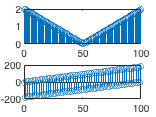


n = 0:100; xn = sinc((n-50)/2).^2; N = length(n); 
Xk = dft(xn,N); k = 0:N-1; 
magXk = abs(Xk); phaXk = angle(Xk)*180/pi; 
figure(1)
subplot(2,1,1);
stem(k,magXk); 
subplot(2,1,2); 
stem(k,phaXk); 

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

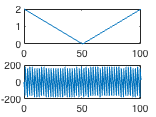



[X,w] = freqz(xn,1,1000,'whole'); 
        
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N; 
figure(2)
subplot(2,1,1); plot(w/Dw,mag_X); 
 
subplot(2,1,2); plot(w/Dw,pha_X); 

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

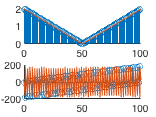



n = 0:100; xn = sinc((n-50)/2).^2; N = length(xn); 
Xk = dft(xn,N); k = 0:N-1; 
magXk = abs(Xk); phaXk = angle(Xk)*180/pi; 
figure(3)
subplot(2,1,1);
hold on 
stem(k,magXk); 
subplot(2,1,2); 
hold on
stem(k,phaXk); 


[X,w] = freqz(xn,1,1000,'whole'); 
        
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N; 
subplot(2,1,1); plot(w/Dw,mag_X); 
 hold off
subplot(2,1,2); plot(w/Dw,pha_X); 
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

%주파수 영역에서의 샘플 개수가 신호의 크기보다 크거나 같으면 x(n)의 DTFT인 X(e^jw)는 이 샘플 값으로부터 
%재구성 할 수 있다.
% x(n)의 신호 개수는 101개이고, 샘플링 개수도 101개 이기 때문에 X(e^jw)로의 재구성 가능하다.

%조건1. Time-limited 되어 있어야 한다.
%조건2. DFT의 sampling rate인 N-point가 신호의 길이(L)보다 크거나 같아야 한다.(N>=L)

function [Xk] = dfs(xn,N)
n = (0:1:N-1);
k = (0:1:N-1);
WN = exp(-1i*2*pi/N);
nk = n'*k;
WNnk = WN .^nk;
Xk = xn * WNnk;
end
function [Xk] = dft(xn,N)
n = (0:1:N-1);
k = (0:1:N-1);
WN = exp(-1i*2*pi/N);
nk = n'*k;
WNnk = WN .^nk;
Xk = xn * WNnk;
end

function [xn] = idft(Xk,N)
n = (0:1:N-1);
k = (0:1:N-1);
WN = exp(-1i*2*pi/N);
nk = n'*k;
WNnk = WN .^(-nk);
xn = (Xk * WNnk)/N;
end

function [X] = dtft(x,n,w)

X = x*exp(-j*n'*w);
end
